clear ;

## Process all data file for one scenario for one participant in one go ( zero degree eight data related to 1.5,2 ,3 4 meter)

filename1='C:\Users\Anuradha\Desktop\Paper 4 Vital Sign\Data Collection Paper 4\Participant 5\40Deg\D1\Phase_save.xlsx';
filename2='C:\Users\Anuradha\Desktop\Paper 4 Vital Sign\Data Collection Paper 4\Participant 5\40Deg\D2\Phase_save.xlsx';
filename3='C:\Users\Anuradha\Desktop\Paper 4 Vital Sign\Data Collection Paper 4\Participant 5\40Deg\D3\Phase_save.xlsx';
filename4='C:\Users\Anuradha\Desktop\Paper 4 Vital Sign\Data Collection Paper 4\Participant 5\40Deg\D4\Phase_save.xlsx';
filename5='C:\Users\Anuradha\Desktop\Paper 4 Vital Sign\Data Collection Paper 4\Participant 5\40Deg\D5\Phase_save.xlsx';
filename6='C:\Users\Anuradha\Desktop\Paper 4 Vital Sign\Data Collection Paper 4\Participant 5\40Deg\D6\Phase_save.xlsx';
filename7='C:\Users\Anuradha\Desktop\Paper 4 Vital Sign\Data Collection Paper 4\Participant 5\40Deg\D7\Phase_save.xlsx';
filename8='C:\Users\Anuradha\Desktop\Paper 4 Vital Sign\Data Collection Paper 4\Participant 5\40Deg\D8\Phase_save.xlsx';

% load complete HR hex file having all data in one sheet from sequence...
% zero deg,20 deg,40 deg,neg20,neg40,diff_posture,clutter 
filename_hex1='C:\Users\Anuradha\Desktop\Paper 4 Vital Sign\Data Collection Paper 4\HexFile_HR.xlsx';
x_heart_all1=readmatrix(filename_hex1);

% to be used for clutter files as one participant is having only four
% dataset in place of eight

filename_hex2='C:\Users\Anuradha\Desktop\Paper 4 Vital Sign\Data Collection Paper 4\HexFile_HR.xlsx';
x_heart_all2=readmatrix(filename_hex2);


%Process all files for a participant in one go
for k= 6:6 %8
    if k==1                                                                      
        filename=filename1;
    elseif k==2
        filename=filename2;
    elseif k==3
        filename=filename3;
    elseif k==4
        filename=filename4;
    elseif k==5
        filename=filename5;
    elseif k==6
        filename=filename6;
    elseif k==7
        filename=filename7;
    elseif k==8
        filename=filename8;
    end
        
    % read phase of each dataset and process

    [filepath,~,~] = fileparts(filename);
    x_phase=readmatrix(filename);

    % read hex file as per dataset number
    if k<9 %use k<5 for clutter files
        % use k+8 for 20 deg, k+16 for 40 deg, k+24 for neg20, k+32 for neg 40
        % k+40 for different postures, k+48 for clutter files
        x_heart=x_heart_all1(:,k); 
        
%     elseif k>4     %use for clutter files
%         x_heart=x_heart_all2(:,k+44);
    end
    

     %process complete signal to check for sustained oscillation dominated
     %frequency for complete test duration
     % 1024 samples best suited for our case where 1512 samples taken for 152 seconds test duration
                r1=3;
                J1=27;
                x_sig=x_phase(257:1280,1); % tested and this number is fixed as optimum for finding data analysis for signal capture 
                [y1,y2,w1,Q1] = myemd_woqop(x_sig);
                [yo1,yo2,wo1,Qo1] = myemd(x_sig);
                
            Q1

Q1 = 8.5238

            Qo1

Qo1 = 12.1000

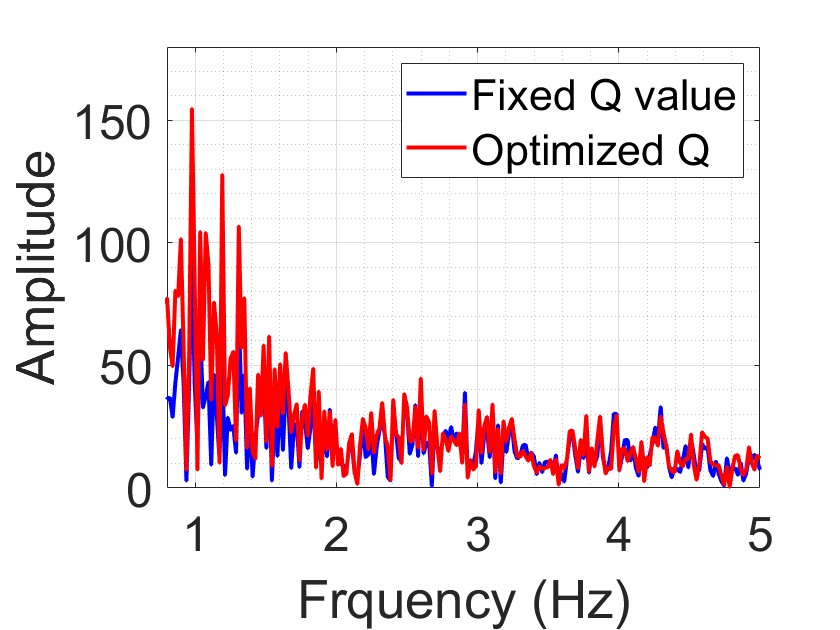

            
            y1_fft = fft(y1,512, 2);
            yo1_fft = fft(yo1,512, 2);
            t1= (1:1024);
            n = (1:512).*(10/512);
            t= n(:, 40:256);
            plot(t,abs(y1_fft(:, 40:256)), 'b', t, abs(yo1_fft(:, 40:256)), 'r', 'LineWidth', 2 )

            grid ON
            grid minor
            xlim([0.8 5])
            ylim([0 180])
            set(gca, "FontSize", 24)
            xlabel('Frquency (Hz)')
            ylabel('Amplitude')
            legend('Fixed Q value','Optimized Q')
%             figure(2)
%             plot(t1,y1, 'b', t1, yo1, 'r')
            
% % % % % %                 e=PlotEnergy(w1);
% % % % % %                 fs=10;
% % % % % %                 if Q1<5
% % % % % %                     J1=22;
% % % % % %                 end
% % % % % %                 fc=tqwt_fc(Q1,r1,J1,fs); %subband centre frequencies
% % % % % %                 hr_test=zeros(2,J1);
% % % % % %                 hr_test(1,:)=fc;
% % % % % %                 hr_test(2,:)=e(1,1:J1);
% % % % % %                 %find out the HR indices fundamental
% % % % % %                 hr_test_1=hr_test(:,(hr_test(1,:)>1));
% % % % % %                 hr_test_1=hr_test_1(:,(hr_test_1(1,:)<1.65));
% % % % % %                 [~,esort]=sort(hr_test_1(2,:),'descend');
% % % % % %                 fc_hr_1=hr_test_1(1,esort);
% % % % % %                 
% % % % % %                 %first harmonic range check index
% % % % % %                 hr_test_2=hr_test(:,(hr_test(1,:)>2.015));
% % % % % %                 hr_test_2=hr_test_2(:,(hr_test_2(1,:)<3.3));
% % % % % %                 [~,esort]=sort(hr_test_2(2,:),'descend');
% % % % % %                 fc_hr_2=hr_test_2(1,esort);
% % % % % %                 if length(fc_hr_1)==2
% % % % % %                     fc_hr_1(3)=fc_hr_1(1);
% % % % % %                 elseif length(fc_hr_1)==1
% % % % % %                     fc_hr_1(2)=fc_hr_1(1);
% % % % % %                     fc_hr_1(3)=fc_hr_1(1);
% % % % % %                 end
% % % % % %                 if length(fc_hr_2)==2
% % % % % %                     fc_hr_2(3)=fc_hr_2(1);
% % % % % %                 elseif length(fc_hr_2)==1
% % % % % %                     fc_hr_2(2)=fc_hr_2(1);
% % % % % %                     fc_hr_2(3)=fc_hr_2(1);
% % % % % %                 end
% % % % % %                 if isempty(fc_hr_1)
% % % % % %                     fc_hr_1=fc_hr_2;
% % % % % %                 end
% % % % % %                 
% % % % % %                 x_heart_radar_1=round(fc_hr_1(1:3),2);
% % % % % %                 x_heart_radar_index1=round(x_heart_radar_1.*51.2);
% % % % % %                 x_heart_radar_2=round(fc_hr_2(1:3),2);
% % % % % %                 x_heart_radar_index2=round(x_heart_radar_2.*51.2/2);
% % % % % %                 index_hr(1,1:3)=x_heart_radar_index1;
% % % % % %                 index_hr(1,4:6)=x_heart_radar_index2;
% % % % % %                 %Find the best rpresentative of frequency in the basic and
% % % % % %                 %first harmonic top three enrgy values
% % % % % %                 h=histogram(index_hr(1,:),'BinWidth',5);
% % % % % %                 [~,idxh]=sort(h.Values,'descend');
% % % % % %                 test_index_check=h.BinEdges(idxh(1))+3; %center of histogram width
% % % % % %                 index_radar=round(test_index_check*600/512)
% % % % % %                
               

## HR harmonic values id estimation through RSSD

% %     ix0=round(60*512/(fs*60))+3;
% %     Nr=length(x_phase); %% 
% %     Nchirp=512;  %% equivalent to 512*100msec = 52sec
% %     init_chirp = 1;
% %     est_window=10; %% equivalent to 10*100msec= 1sec
% %     noofestimates = round((Nr - Nchirp)/est_window);
% %     ihh=zeros(noofestimates,6);
% %     for p = 1:noofestimates
% %         end_chirp = init_chirp+Nchirp-1;
% %         x_sig=x_phase(init_chirp:end_chirp);
% %         init_chirp= p*est_window +1;
% %         [y1,y2,w1] = myemd_sec(x_sig,Q1);
% %                 e=PlotEnergy(w1);
% %                 fc=tqwt_fc(Q1,r1,J1,fs);
% %                 hr_test=zeros(2,J1);
% %                 hr_test(1,:)=fc;
% %                 hr_test(2,:)=e(1,1:J1);
% %                 %find out the HR indices fundamental
% %                 hr_test_1=hr_test(:,(hr_test(1,:)>1));
% %                 hr_test_1=hr_test_1(:,(hr_test_1(1,:)<1.65));
% %                 [~,esort]=sort(hr_test_1(2,:),'descend');
% %                 fc_hr_1=hr_test_1(1,esort);
% %                 
% %                 %first harmonic range check index
% %                 hr_test_2=hr_test(:,(hr_test(1,:)>2.015));
% %                 hr_test_2=hr_test_2(:,(hr_test_2(1,:)<3.3));
% %                 [~,esort]=sort(hr_test_2(2,:),'descend');
% %                 fc_hr_2=hr_test_2(1,esort);
% %                 if length(fc_hr_1)==2
% %                     fc_hr_1(3)=fc_hr_1(1);
% %                 elseif length(fc_hr_1)==1
% %                     fc_hr_1(2)=fc_hr_1(1);
% %                     fc_hr_1(3)=fc_hr_1(1);
% %                 end
% %                 if length(fc_hr_2)==2
% %                     fc_hr_2(3)=fc_hr_2(1);
% %                 elseif length(fc_hr_2)==1
% %                     fc_hr_2(2)=fc_hr_2(1);
% %                     fc_hr_2(3)=fc_hr_2(1);
% %                 end
% %                 if isempty(fc_hr_1)
% %                     fc_hr_1=fc_hr_2;
% %                 end
% %                 
% %                 x_heart_radar_1=round(fc_hr_1(1:3),2);
% %                 x_heart_radar_index1=round(x_heart_radar_1.*51.2);
% %                 x_heart_radar_2=round(fc_hr_2(1:3),2);
% %                 x_heart_radar_index2=round(x_heart_radar_2.*51.2/2);
% %                 ihh(p,1:3)=x_heart_radar_index1;
% %                 ihh(p,4:6)=x_heart_radar_index2;
% %     end

    

% %     %write all hr index in a file
% %     noofestimates=100;
% %     hr_hex=x_heart(52:51+noofestimates,1);
% %     hr_hex_ind=round(hr_hex*512/600);
% %     hr_ind_cpm=ihh;
% %     hr_ind_cpm(:,7)=index_radar;
% %     hr_ind_cpm(:,8)=hr_hex_ind;
% %     f2 = fullfile(filepath,"hr_radar_index.xlsx");
% %     writematrix(hr_ind_cpm,f2);
end
